Throughput = calculate_throughput(TBS, BLER)

Throughput = 5×1 cell array
    {1000×1 double}
    {1000×1 double}
    {1000×1 double}
    {1000×1 double}
    {1000×1 double}


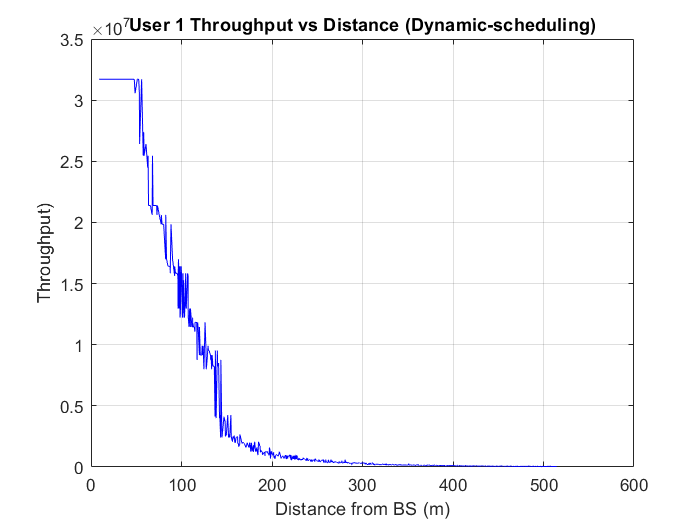

figure; plot(ds, Throughput{1}(idx), 'b-'); grid on
xlabel('Distance from BS (m)'); ylabel('Throughput)');
title('User 1 Throughput vs Distance (Dynamic-scheduling)');

function Throughput = calculate_throughput(TBS, BLER)
    % CALCULATE_THROUGHPUT - Calculates throughput for 5 users based on TBS and BLER
    %
    % Inputs:
    %   TBS  - Cell array containing Transport Block Size for each user (bits)
    %   BLER - Cell array containing Block Error Rate for each user
    %   TTI  - Transmission Time Interval in seconds (default: 0.001 = 1ms)
    %
    % Outputs:
    %   Throughput - Cell array containing throughput for each user (bits/second)
    
    % Default TTI to 1ms if not provided

        TTI = 0.001;  % 1ms in seconds
    
    
    % Validate inputs
    if length(TBS) ~= 5 || length(BLER) ~= 5
        error('TBS and BLER must be cell arrays with exactly 5 elements (one for each user)');
    end
    
    % Initialize output cell array
    num_users = 5;
    Throughput = cell(num_users, 1);
    
    % Process each user
    for user = 1:num_users
        current_tbs = TBS{user};
        current_bler = BLER{user};
        
        % Ensure TBS and BLER arrays have the same length
        if length(current_tbs) ~= length(current_bler)
            error('TBS and BLER arrays must have the same length for User %d', user);
        end
        
        num_samples = length(current_tbs);
        user_throughput = zeros(size(current_tbs));
        
        % Calculate throughput for each sample
        for sample = 1:num_samples
            tbs_val = current_tbs(sample);
            bler_val = current_bler(sample);
            
            % Calculate attempts needed
            [attempts,a] = calculate_attempts(bler_val);
            
            % Calculate throughput: Throughput = TBS / (TTI * Attempts)
            if tbs_val > 0 && attempts > 0
                user_throughput(sample) = a*(tbs_val / (TTI * attempts));
            else
                user_throughput(sample) = 0;
            end
        end
        
        % Store throughput results for current user
        Throughput{user} = user_throughput;
    end
end

function [attempts, a] = calculate_attempts(bler)
    % CALCULATE_ATTEMPTS - Determines number of transmission attempts needed
    %
    % Input:
    %   bler - Block Error Rate (0 to 1)
    %
    % Output:
    %   attempts - Number of transmission attempts needed
    
    % Initialize attempts counter
    attempts = 1;  % Start with 1 attempt
    current_bler = bler;
    a=1;
    
    % Keep reducing BLER by 1/3 until it's <= 0.1
    while current_bler > 0.1
        current_bler = current_bler * (1/3);
        attempts = attempts + 1;
        
        % Safety check to prevent infinite loop (in case of numerical issues)
        if attempts > 4
            a=0;
            break;
        end
    end
end